clear
load new_90.8.mat

## Exercise 1

% c)
figure;
%plot the FFT of y_I
plot_FT(y_I,fs)

ans = 	1.0e+06 *

   0.0472 + 0.0000i
  -0.0052 - 0.0152i
   0.0487 - 0.0231i
  -0.0048 + 0.0573i
   0.0140 - 0.0013i
  -0.0139 + 0.0145i
   0.0033 - 0.0344i
   0.0233 + 0.0273i
  -0.0279 + 0.0037i
   0.0162 + 0.0257i


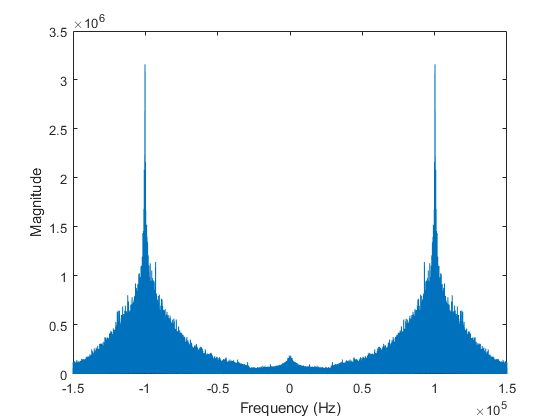

xlabel('Frequency (Hz)');
ylabel('Magnitude')
print('-dsvg', 'yi.svg');

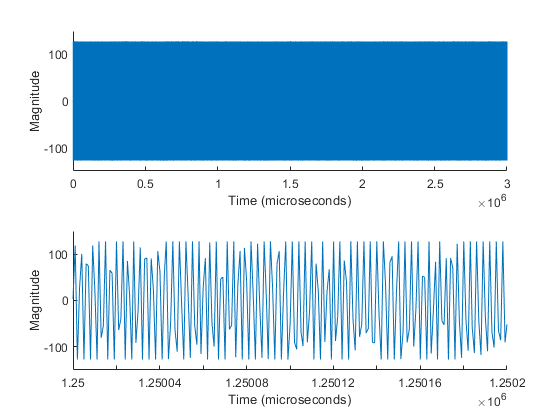

% d)
figure;
%plot the time domain signal of y_I
subplot(2, 1, 1);
axis([-100 3000000 -150 150]);
xlabel("Time (microseconds)");
ylabel('Magnitude')
hold on;
plot(y_I);
hold off;

%plot the zoomed in time domain signal of y_I to prove it's FM
subplot(2, 1, 2);
xlabel("Time (microseconds)");
ylabel('Magnitude')
axis([1.25e6 1.2502e6 -150 150]);
hold on;
plot(y_I);
hold off;

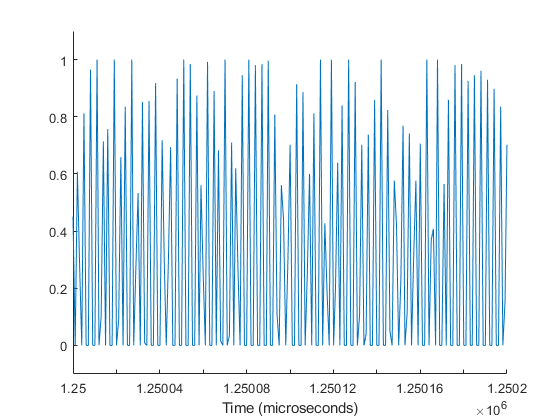

% e)

%take the deriv of y_I
diff_y_I = diff(y_I);

%delete all negative values
nonzerodiff_y_I = diff_y_I;
for i = 1:length(nonzerodiff_y_I)-1
    nonzerodiff_y_I(i) = y_I(i+1) - y_I(i);
    if nonzerodiff_y_I(i)<0
        nonzerodiff_y_I(i)=0;
    end
end
nonzerodiff_y_I;

%normalize to make the max value 1
nonzerodiff_y_I = nonzerodiff_y_I ./ max(nonzerodiff_y_I);

%plot the normalized y_I
figure;
xlabel("Time (microseconds)");
%title("Derivative of y_I");
axis([1.25e6 1.2502e6 -0.1 1.1]);
%axis([1.5e6 1.55e6 -0.1 1.1]);
hold on;
plot(nonzerodiff_y_I);
hold off;

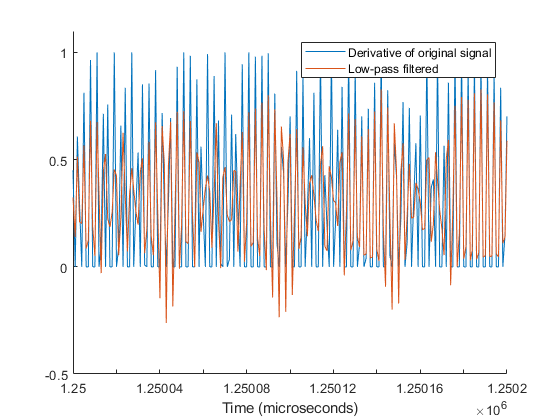

%f)

%lpf y_I, then normalize it again
nonzerodiff_y_I_filt = lowpass(nonzerodiff_y_I, 100000, fs);
nonzerodiff_y_I_filt = nonzerodiff_y_I_filt ./ max(nonzerodiff_y_I_filt);

%plot the filtered and normalized version of y_I
figure;
%axis([1.5e6 1.55e6 -0.1 1.1]);
axis([1.25e6 1.2502e6 -0.5 1.1]);
xlabel("Time (microseconds)");
%title("Signal filtered");
hold on;
plot(nonzerodiff_y_I, "DisplayName", "Derivative of original signal");
plot(nonzerodiff_y_I_filt, "DisplayName", "Low-pass filtered");
legend;
print('-dsvg', 'yi.svg');
hold off;

% Part g

%play the sound by subtracting by the mean, multiplying by 0.1, and normalizing
nonzerodiff_y_I_filt_shifted = nonzerodiff_y_I_filt - mean(nonzerodiff_y_I_filt);
nonzerodiff_y_I_filt_shifted = nonzerodiff_y_I_filt_shifted * 0.1 ./ max(nonzerodiff_y_I_filt_shifted);

%decimate
nonzerodiff_y_I_filt_shifted_decimated = decimate(nonzerodiff_y_I_filt_shifted, 4);

%play the sound
sound(nonzerodiff_y_I_filt_shifted_decimated, 300000/4);

## Exercise 2

clear
load('new_90.8.mat')

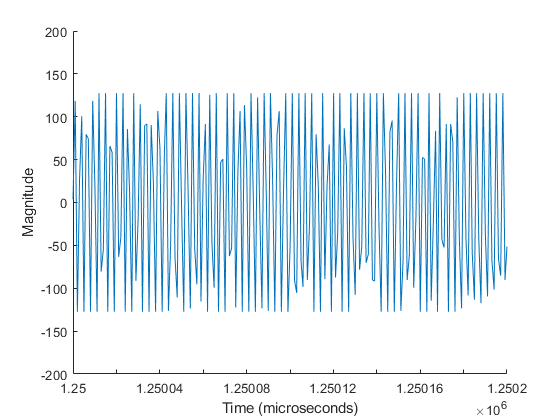

%plot the time domain signal of y_I
figure
axis([1.25e6 1.2502e6 -200 200]);
xlabel('Time (microseconds)')
ylabel('Magnitude')
hold on
plot(y_I);
hold off

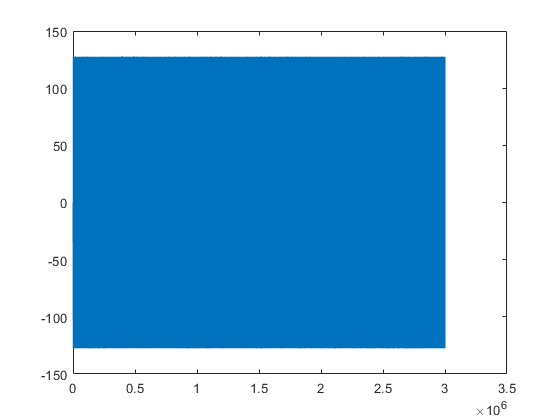


%plot the time domain signal of y_Q
figure
axis([1.25e6 1.2502e6 -200 200]);
xlabel('Time (microseconds)')
ylabel('Magnitude')
hold on
plot(y_Q);
hold off

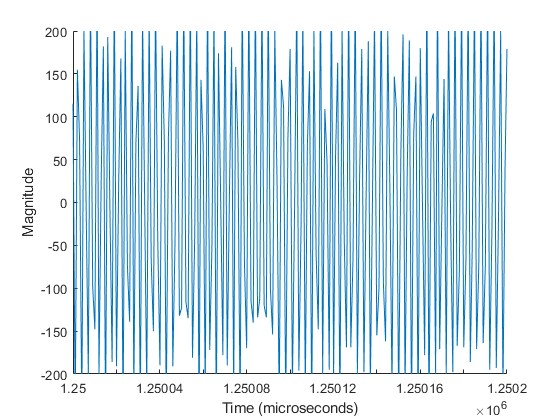

%take the derivative of both y_I and y_Q
diff_yi = diff(y_I);
diff_yq = diff(y_Q);

%plot the deriv of y_I
figure
axis([1.25e6 1.2502e6 -200 200]);
xlabel('Time (microseconds)')
ylabel('Magnitude')
hold on
plot(diff_yi);
hold off

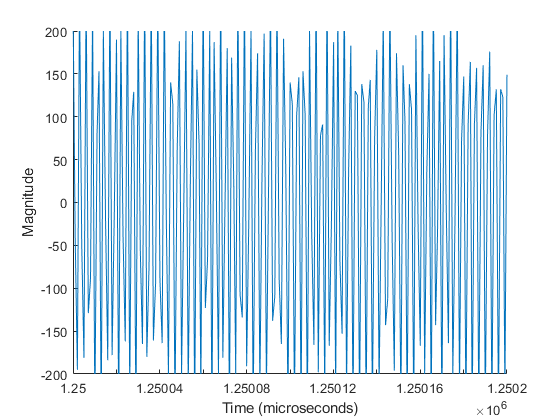


%plot the deriv of y_Q
figure
axis([1.25e6 1.2502e6 -200 200]);
xlabel('Time (microseconds)')
ylabel('Magnitude')
hold on
plot(diff_yq);
hold off

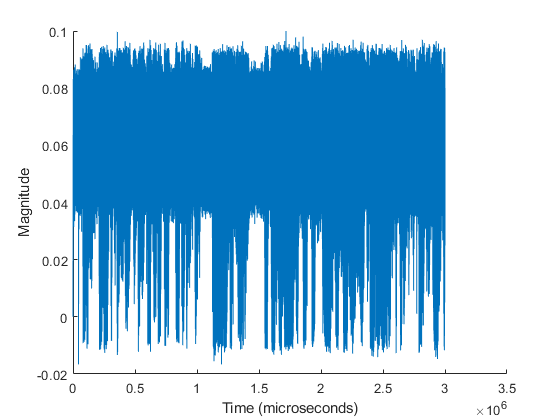

%implement the provided equation for mhat
diff1 = diff_yq .* y_I(1:end-1,:);
diff2 = diff_yi .* y_Q(1:end-1,:);
mhat = diff1 - diff2;

%use the same steps as in previous exercise to play the sound
diffs_nm = mhat - mean(mhat);
diffs_norm = mhat * 0.1 / max(abs(mhat));
diffs_dec = decimate(diffs_norm, 4);

figure
xlabel('Time (microseconds)')
ylabel('Magnitude')
hold on
plot(diffs_norm);
hold off


%play the sound
% audiowrite(diffs_dec,y,fs);

Undefined function or variable 'y'.

% [y,fs] = audioread(diffs_dec);
sound(diffs_dec, 300000/4)

